## **Exercício 3**

**(a)**

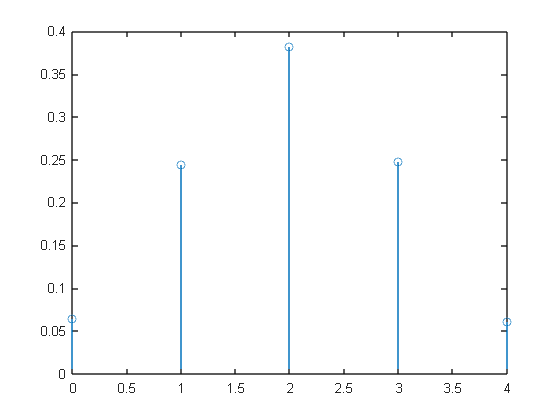

N = 10000;

exp = rand(4,N) <= 0.5;
num = sum(exp);

X = 0:4;
fX = zeros(1,5);

for i = X
    fX(i+1) = sum(num==i)/N;
end
stem(X, fX)

**(b)**

valorEsp = 0;

for i = 0:4
    valorEsp = valorEsp + (i * fX(i+1));
end
valorEsp

valorEsp = 1.9963

E_x2_ = 0;
for i = 0:4
    E_x2_ = E_x2_ + (pow2(i) * fX(i+1));
end
Ex_2 = valorEsp^2;
variancia = E_x2_ - Ex_2

variancia = 1.0534

desvioPadrao = sqrt(variancia)

desvioPadrao = 1.0263

**(c)**

% Esta variável aleatória apresenta o comportamento de uma distribuição binomial
% visto que temos 4 repetições de uma experiência de Bernoulli. (no lançamento de
% uma moeda, podemos encarar que temos sucesso quando calha coroa e insucesso
% quando calha cara)

% A expressão teórica da função de probabilidade é:
% pX(k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)

**(d)**

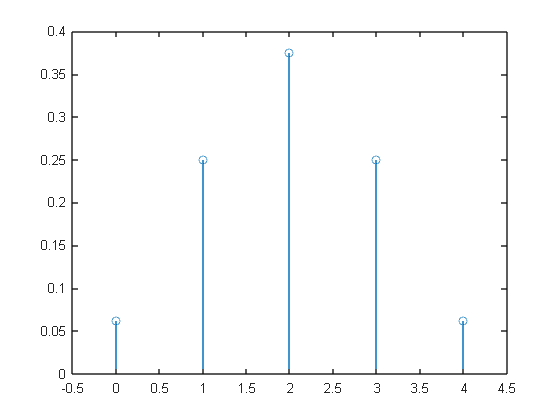

% n = 4, que é o total
% k vai de 0 a 4
n = 4;
p = 0.5;
pX = zeros(1,5);

for i = 1:5
    k = i - 1;
    pX(i) = factorial(n) / (factorial(k) * factorial(n-k)) * p^k * (1-p)^(n-k);
end

pX;
x = 0:4;
stem(x,pX);
axis([-0.5 4.5 0 0.4]);

**(e)**

**(f)**

p = sum(pX(x >= 2))

p = 0.6875

p = sum(pX(x <= 1))

p = 0.3125

p = sum(pX(x >= 1 & x <= 3))

p = 0.8750